# 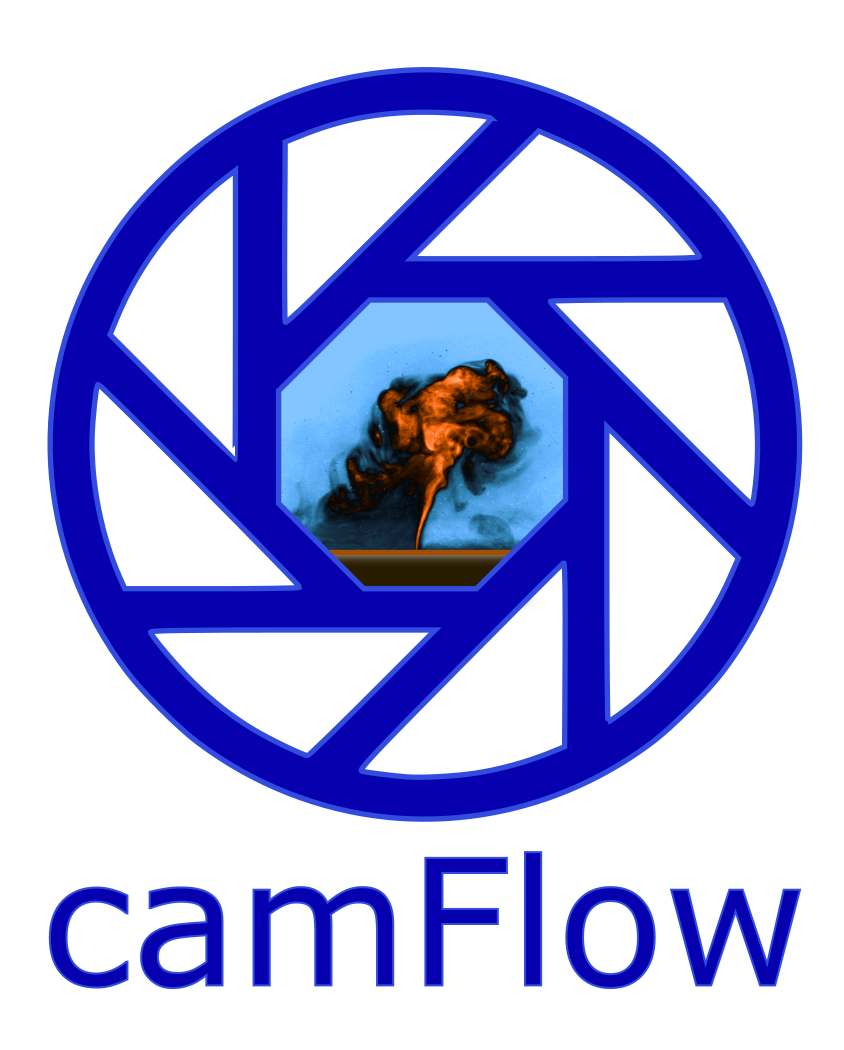                                                                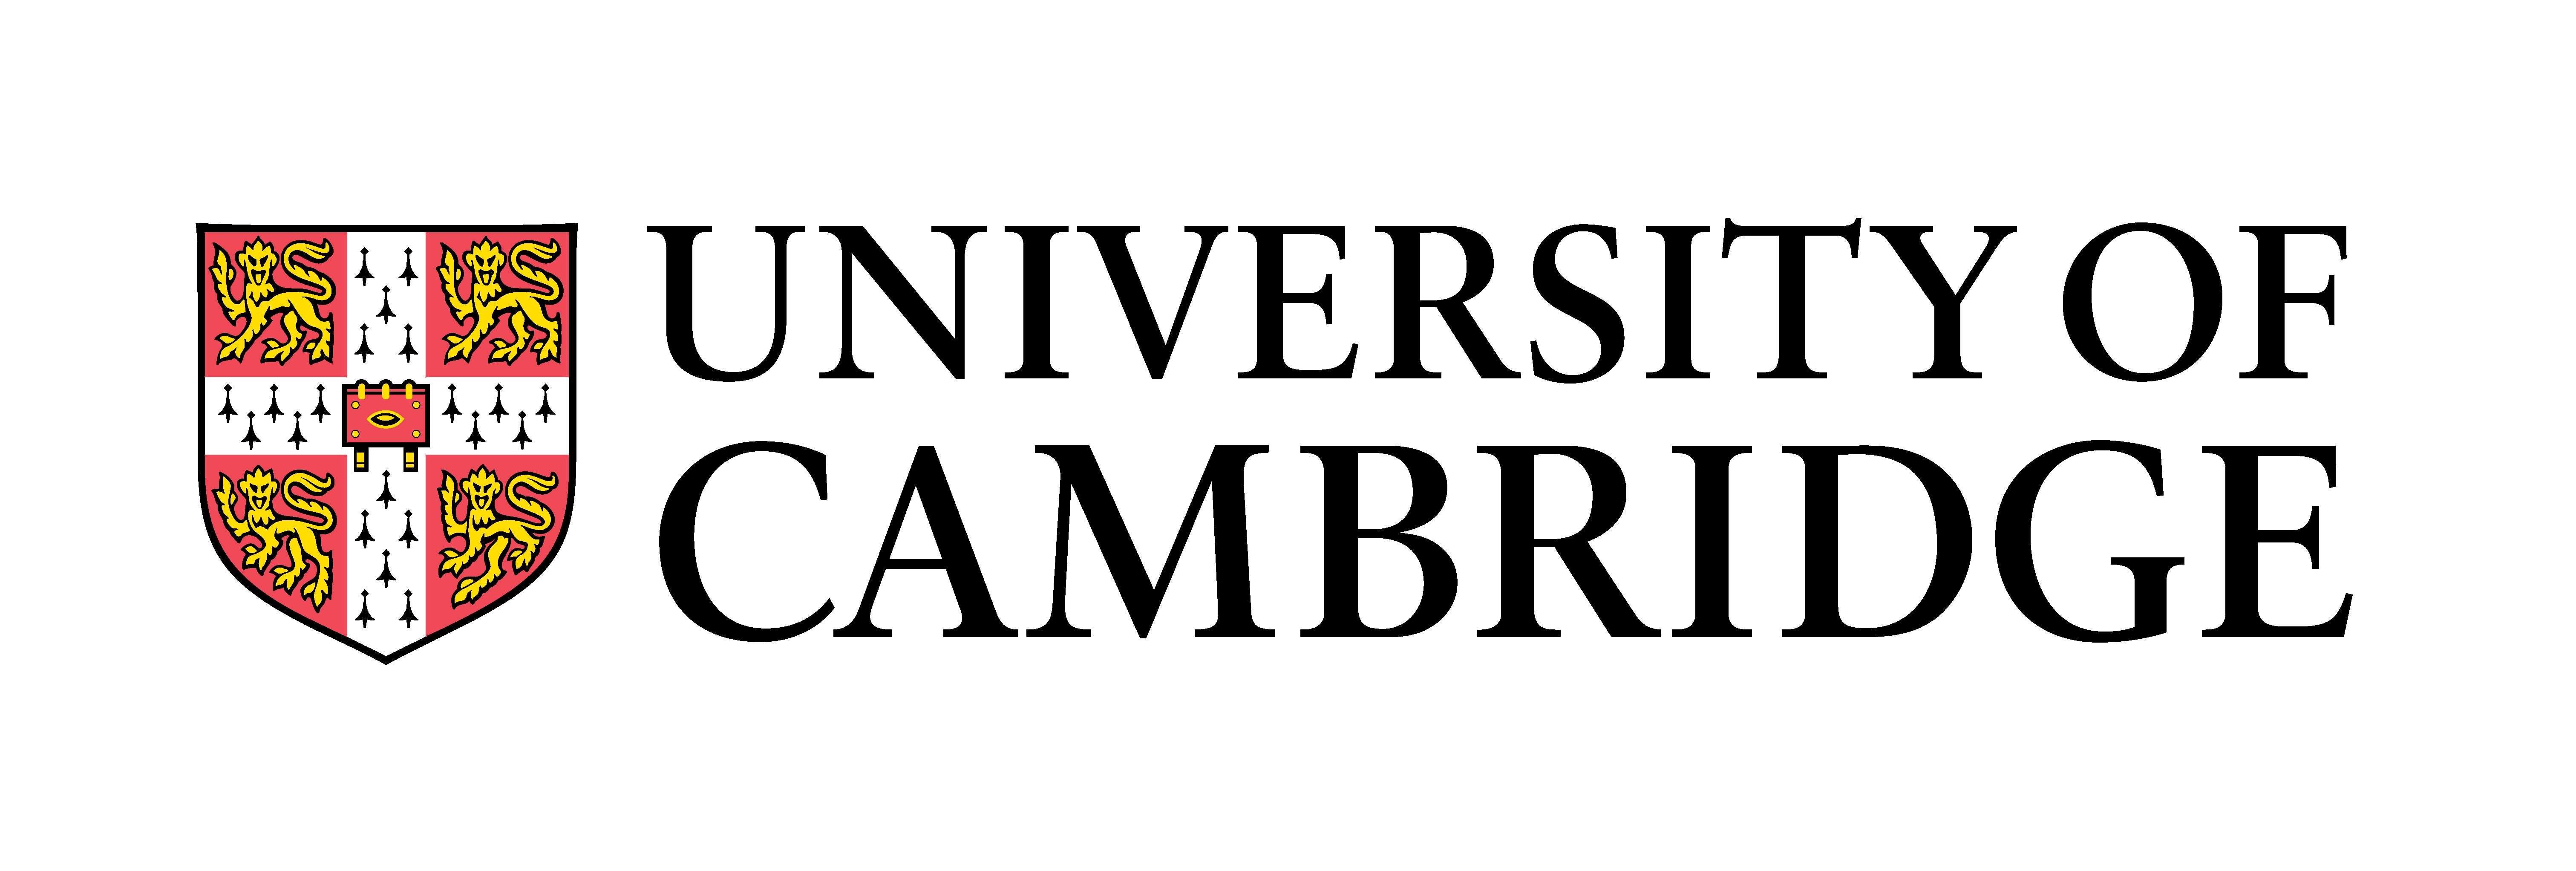

# Video acquisition with camFlowAq

The **camFlowAq** toolbox has been developed by F. Ciriello to provide a framework for G. R. Hunt's research group to share acquisition and processing tools. It uses the **camFlowAq **class, which you can download from [github.com/FrancescoCiriello](http://www.github.com/FrancescoCiriello) (or on request at **fc397@cam.ac.uk**). You can add to your MATLAB userpath, finding it via running

userpath

in the command prompt, or add it into your MATLAB environment path in **Home>Environment>Set Path**.

Make sure you have updated MATLAB! The toolbox has been tested on MATLAB 2018b-2019a. 

I would recommend to set the **current directory** to the main project folder you are working in to ensure that outputs are stored in an appropriate location. 

cd D:\Users\fc397\Documents\myProject

## How to use the camFlow Acquisition toolbox

I have created the video acquisition class (**camFlowAq**) to process video streams from monochrome scientific cameras that use the *GenICam* protocol (tested on JAI Spark 5000-M-USB). 

Users can use **help** functions for more information on any of the functions used in this class.

For example, to get more info on the **camFlowAq** class (as a whole) by simply typing in the command window

help camFlowAq

The class allows a user to create an "*acquisition*" object and use in-built methods to perform common tasks, including:

- load a camera videostream (**camFlowAq**)

- preview a live stream from the camera (**preview**, **advancedPreview**)

- crop to a region of interest ROI (**crop**)

- change, save and load pre-defined settings (**camSettings**)

- recolor live stream in false colour (**camColor**)

- open a tool to assist in manual focus (**camFocus)**

- calibrate camera (**camCalibrate**)

- acquire video and save into a .avi file (**acquire**)

- acquire background frames and save into a .avi movie and .tif imae (**acquireBackground**)

Furthermore, the toolbox can be used to apply a range of **live image processing** algorithms, including:

- background subtractions (**livebackgroundSubtract)**

- detect edges (**liveEdge)**

- motion detection with optical flow methods (**liveOF)**

- process singleshot PIV image pair  (**livePIV**)

and post-processing features:

- extract raw frames from movie file (**extractFrames**)

- background subtract images (**backgroundSubtract**)

## Acquisition functionalities

In case of trouble, reset camera connection via:

imaqreset;   

### Basics

#### Load camera

Create an acquisition object (**cam**) using the **camFlowAq** class file. The first argument allows you to choose the camera interface. You can choose a GenICam interface using  '**gentl**' and a standard webcam interface using '**winvideo**'. You can select the which camera to connect to with the optional second argument (default device #1). You can specify the camera format with the third optional argument (default format is camera pre-selected format).

cam = camFlowAq('gentl',1,'Mono8');
% cam = camFlowAq('winvideo',1,'MJPG_848x480');

Available formats are stored in the objects **obj.info** property:

cam.info.DeviceInfo.SupportedFormats;

#### Camera controls

The **camSettings **functions opens up a dialog box with the most commonly-used options for camera settings.

camSettings(cam)

Note that **camSettings** cannot be used when **preview / acquisition** is active if *exposure fps* = *acquisition fps*. Also note that **camSettings** does not work with the **advancedPreview** function due to callback errors.

All other controls can be accessed simply via **cam1.camera.src.*****controlName. ***For example, to change the gain of the camera you can use:

cam.camera.src.Gain = 2;

A list of camera controls can be inspected with the **get** function.

get(cam.camera.src)

The **camSettings** function also has save and load functionalities. These are stored in the *cameraSettings* directory.

camSettings(cam,'save','mySettings')
camSettings(cam,'load','mySettings')

#### Preview

The live stream from the camera is contained with the **obj.liveStream** property handle. You can modify the live stream in different ways. Axis properties are in **obj.liveStream.Parent **and figure properties are in **obj.liveStream.Parent.Parent**.

Note that the **preview** function from the image acquisition toolbox has been overloaded for that it can take in the **videoJaiAq** class and it creates its own figure handle object (*i.e.* the aforementioned **obj.liveStream)**  from the videoinput object**. **

preview(cam)

An **advancedPreview **function is also available to inspect the grey levels in the image and detect saturation levels.

advancedPreview(cam); 

The **camColor** function allows to change the colormap for the current live stream. The live stream must be open. This is a useful feature to detect saturation levels. I have created a bespoke colour map to highlight saturated regions called **satColor **(a grey scale with red and green indicating black and white saturated respectively). 

camColor(cam,gray)   % default
camColor(cam,jet)    % you can use any pre-defined MATLAB colormap
camColor(cam, 'satColor')

#### Acquisition

The **acquireBackground** function acquires 100 frames by default and stores the average of the acquired frames as the background in **obj.background.image**. An optional second argument can be used to change the number of background frames to acquire.

acquireBackground(cam,10)     

You can inspect the background image with:

imshow(cam.background.frame)

The **acquire** function can be used to record a avi movie. A dialog box appears to start acquisition manually.  

acquire(cam,'on','on',10,'myMovieName')

Default outputs are named '**raw.avi**' and placed in the **exp* **folder. 

A second optional argument **saves the background video** to the same directory ('on' or 'off'). 

A third optional argument **saves the calibration **to the same directory ('on' or 'off'). 

A fourth optional argument specifies the **number of frames** to acquire for. 

A fifth optional argument manually sets the **filename.**

A sixth optional argument specifies whether to **acquire with live stream **'on' or 'off'.

A single image can be acquired with

img = getsnapshot(cam.camera.vid);
imwrite(img, 'outputs/image.tif');

#### Playback

Any video can be replayed using MATLAB's **implay** function.

implay('outputs/exp1/raw.avi')

### Preview Tools

#### Cropping

The **crop** function can be used after **preview** or as a standalone **preview&crop** function. The **advancedPreview** function can also be used in conjuction with **crop**. The function asks for a user-input for an ROI that can be drawn directly on the live stream. The ROI can be adjusted and confirmed with a double-click.

crop(cam)

The **cropReset** function resets the cropping to the original camera resolution.

cropReset(cam)

The **camFocus** function has been designed to assist in manual focus mode. A user-prompted rectangle is required to zoom into a region that requires focus. This opens up a new figure window with the zoomed in image and a plot that shows strips of pixel intensities. The more detail in the single the better the focus.

camFocus(cam); 

#### **Calibration**

The **camCalibrate** function assists calibration of the camera by taking processing images of a real-world object of known size. All properties stored in **obj.calibration**. 

**Line calibrator: **A '**line**' argument applies a simple linear calibration of px to mm requiring a user-input. 

camCalibrate(cam,'line'); 

**Plate calibrator: **A '**checker**' board argument guides the user through a more advanced calibration. $x$ images (by default, $x=10$, at least $3$, ideally $10-20$)  are acquired of a checkerboard placed at different orientations and positions. The function deduces *extrinsic* camera parameters (**obj.calibration.cameraParams**). To simplify use, a px size in mm is stored in **obj.calibration.pxsize **relative to the first calibration plane.

camCalibrate(cam,'checker',squareSize,numCalibrationImages)    % squareSize in mm
camCalibrate(cam,'checker',13,5)

The checker board calibration, amongst other functionalities, allows you to reproject images so that you can remove warping effects using the **undistortImage** function:

rawImage = getsnapshot(cam.camera.vid);
undistortedImage = undistortImage(rawImage,cam.calibration.cameraParams);
subplot(1,2,1)
imshow(rawImage)
subplot(1,2,2)
imshow(undistortedImage)

For GUI guided camera calibration, you can use MATLAB's **cameraCalibrator** app:

cameraCalibrator

and find **more information** on camera calibration: [https://uk.mathworks.com/help/vision/ug/camera-calibration.html](https://uk.mathworks.com/help/vision/ug/camera-calibration.html)

A '**dye**' argument can be used to apply a dye calibration using a dye-filled prism.

camCalibrate(cam,'dye') % this feature is under development

## Multi-camera acquisition

Several cameras can be loaded as different objects

cam1 = videoJaiAq(1,'Mono8');
cam2 = videoJaiAq(2,'Mono8');

Multi-camera functionalities are the same as the single-camera functionalities described in the **Basics** section. Simply insert the camera objects as an array.

preview([cam1, cam2])
acquireBackground([cam1, cam2],10)
acquire([cam1, cam2],'on','on',100,'myMovieName','on');

#### Stereo calibration

The **camStereoCalibrate** function can be used to calibrate to or more cameras to enable stereoscopic vision functionalities.

camStereoCalibrate([cam1, cam2],13,10)   % args = {[camarray],squareSize,numCalibImages}

MATLAB's GUI for stereo calibration can be launched with:

stereoCameraCalibrator

Once the calibration is complete, you can acquire stereoscopic images and videos.

rawImage1 = getsnapshot(cam1.camera.vid);
rawImage2 = getsnapshot(cam2.camera.vid);

[rectImage1, rectImage2] = rectifyStereoImages(rawImage1, rawImage2, cam1.stereoCalibration.stereoParams);

disparityMap = disparity(rectImage1, rectImage2);

imshow(stereoAnaglyph(rectImage1, rectImage2))
imagesc(disparityMap)

## Live image processing

There are a number of functionalities here that are being developed.

#### Live background subtraction

A live background subtraction can be applied to the live stream by using:

liveBackgroundSubtract(cam)

Other live image processing methods are available in:

camLivestream(cam,process)

## Post-processing

The extract frames function can be used to batch save all images from a file.

extractFrames('outputs/exp1/raw.avi') % under development

I would recommend not to use **extractFrames**. You can read frames using a **videoreader** object:

video = VideoReader('outputs/exp1/raw.avi')
frame = read(video,2)    % reading second frame (n.b. first frame often black)

The **makeVideo** function opens a GUI with **imaqmontage** and allows you to choose background subtraction, fps, moviename, and contrast adjustments.

## Installing the JAI cameras to use in MATLAB

There are a few necessary steps to setup acquisition with the JAI camera in MATLAB and use the toolbox. These are:

**   1. **Install **Jai SDK **from [https://www.jai.com/support-software/jai-software.](https://www.jai.com/support-software/jai-software) 

**   2.** Install MATLAB with the** image acquisition**,** image processing**, **computer vision** toolboxes from [https://uk.mathworks.com/downloads/.](https://uk.mathworks.com/downloads/.)

**   3.** Install MATLAB hardware **adaptor for GenICam** (search for 'genicam adaptor' in MATLAB Apps)

**   4. **Add Jai SDK directory to **environment variables **

go to** System Properties** > **Advanced** > **Environment Variables**

add new system variable

> Variable Name : **GENICAM_GENTL64_PATH** 

> Variable value : **C:\Program Files\JAI\SDK\bin** 

Change the variable name depending on whether computer is 32 or 64 bits and the variable value depending on your path directory for the Jai SDK. I would suggest to either type the variable names and values or to copy & paste these in after you got rid of formatting (e.g. you could do this by copy & pasting these in your browser search bar and then copy & paste again in the environment variable dialog boxes).

**   5. Restart** **MATLAB**

## **Known compatibility issues**

- **False colour:** Older versions of MATLAB (prior 2017b ) hold the **colormap** property in the figure object rather than the axis. This causes problems when using false color in live streams.